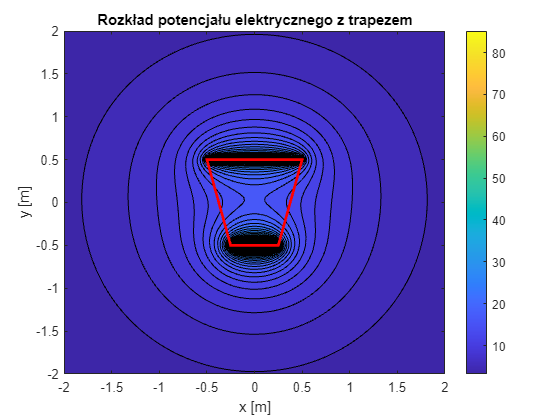


    % Parametry trapezu
    a = 0.5; % długość krótszej podstawy
    b = 1.0; % długość dłuższej podstawy
    h = 1.0; % wysokość trapezu
    Q = 1e-9; % całkowity ładunek na trapezie
    epsilon_0 = 8.854187817e-12; % przenikalność próżni

    % Dyskretyzacja trapezu na ładunki punktowe
    num_points = 1000; % liczba punktów dyskretyzacji

    % Rozłożenie ładunków wzdłuż górnej i dolnej krawędzi trapezu
    x_top = linspace(-b/2, b/2, num_points);
    x_bottom = linspace(-a/2, a/2, num_points);
    y_top = h/2 * ones(1, num_points);
    y_bottom = -h/2 * ones(1, num_points);

    % Połączenie krawędzi górnej i dolnej
    x_charge = [x_top x_bottom];
    y_charge = [y_top y_bottom];
    % Rozłożenie ładunku równomiernie
    dq = Q / (2*num_points); % ładunek na jeden punkt dyskretyzacji

    % Definiowanie siatki obliczeniowej
    [X, Y] = meshgrid(linspace(-2, 2, 100), linspace(-2, 2, 100));
    V = zeros(size(X)); % inicjalizacja macierzy potencjału
    Ex = zeros(size(X)); % inicjalizacja macierzy składowej X pola
    Ey = zeros(size(X)); % inicjalizacja macierzy składowej Y pola

    % Obliczenie potencjału i pola elektrycznego
    for i = 1:length(x_charge)
        r = sqrt((X - x_charge(i)).^2 + (Y - y_charge(i)).^2);
        V = V + dq ./ (4 * pi * epsilon_0 * r);
    end

    % Obliczenie składowych pola elektrycznego poprzez różniczkowanie potencjału
    [Ex, Ey] = gradient(-V);

    % Rysowanie wykresu potencjału z naniesionym trapezem
figure;
contourf(X, Y, V, 50); hold on;
plot_trapezoid(a, b, h);
title('Rozkład potencjału elektrycznego z trapezem');
xlabel('x [m]');
ylabel('y [m]');
colorbar;
hold off;

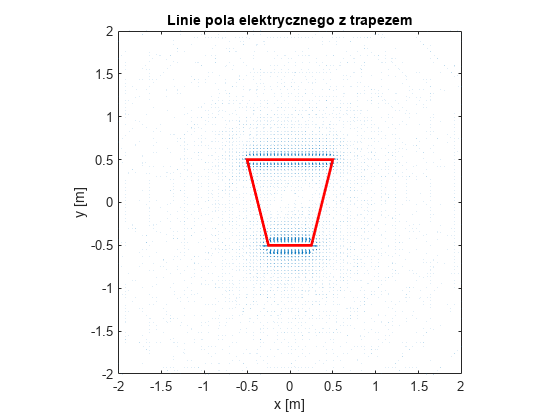


% Rysowanie wykresu linii pola elektrycznego z naniesionym trapezem
figure;
quiver(X, Y, Ex, Ey); hold on;
plot_trapezoid(a, b, h);
title('Linie pola elektrycznego z trapezem');
xlabel('x [m]');
ylabel('y [m]');
axis equal tight;
hold off;


% Funkcja do rysowania trapezu na wykresie

function plot_trapezoid(a, b, h)
    % Wierzchołki trapezu
    vertices = [-a/2, -h/2;
                 a/2, -h/2;
                 b/2,  h/2;
                -b/2,  h/2];
    % Rysowanie trapezu
    patch('Faces', [1 2 3 4], 'Vertices', vertices, 'EdgeColor', 'r', 'FaceColor', 'none', 'LineWidth', 2);
end